# create downsampled vector of all aluminum times without the artifact times


run(params_path)

experiment = auditory_ephys_exp(params_path);

data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
%aud_data = data.Data.Data.mapped(32 + mic,:)

% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 402

expLength = length(data.Data.Data.mapped)

expLength = 67777280

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 902439

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449   450   451


sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        74828
       74966
       75038
       75115
       75211
       75266
       75342
       75414
       75486
       75561



[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))

faceStart = 101

faceVector = [faceStart:faceStart+length(whiskingVector)-1]

faceVector =    101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150


% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30

artifactStart = 75000

artifactEnd = experiment.Conditions.artifact_times(1) * 30

artifactEnd = 90000

all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = 34×2 int64 matrix
    4780464    6505018
    6670018    8394572
    8559572   10272128
   10437128   12149685
   12314685   14033243
   14198243   15910800
   16075800   17800355
   17965355   19677955
   19842955   21567509
   21732509   23457064


aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)

aluminumTimes = 15×2 int64 matrix
   10437128   12149685
   12314685   14033243
   16075800   17800355
   19842955   21567509
   25499620   27218179
   31150290   32874844
   34917444   36630001
   36795001   38513559
   48102340   49814940
   49979940   51704494


% create idx vector for aluminum
aluminumInd = []


aluminumInd =

     []



for al = 1:length(aluminumTimes)
    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))
    aluminumInd = [aluminumInd;tempInd]
end

tempInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       163067
      163068
      163069
      163070
      163071
      163072
      163073
      163074
      163075
      163076


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       213183
      213184
      213185
      213186
      213187
      213188
      213189
      213190
      213191
      213192


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       263372
      263373
      263374
      263375
      263376
      263377
      263378
      263379
      263380
      263381


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       338741
      338742
      338743
      338744
      338745
      338746
      338747
      338748
      338749
      338750


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       414032
      414033
      414034
      414035
      414036
      414037
      414038
      414039
      414040
      414041


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       464225
      464226
      464227
      464228
      464229
      464230
      464231
      464232
      464233
      464234


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       489242
      489243
      489244
      489245
      489246
      489247
      489248
      489249
      489250
      489251


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       639902
      639903
      639904
      639905
      639906
      639907
      639908
      639909
      639910
      639911


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       664919
      664920
      664921
      664922
      664923
      664924
      664925
      664926
      664927
      664928


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       740210
      740211
      740212
      740213
      740214
      740215
      740216
      740217
      740218
      740219


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       765225
      765226
      765227
      765228
      765229
      765230
      765231
      765232
      765233
      765234


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       790238
      790239
      790240
      790241
      790242
      790243
      790244
      790245
      790246
      790247


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       815254
      815255
      815256
      815257
      815258
      815259
      815260
      815261
      815262
      815263


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       890535
      890536
      890537
      890538
      890539
      890540
      890541
      890542
      890543
      890544


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)

aluminumVector =     10437131
    10437194
    10437277
    10437350
    10437430
    10437497
    10437581
    10437650
    10437729
    10437797


% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'

aluminumWhiskerVector =       138454
      138455
      138456
      138457
      138458
      138459
      138460
      138461
      138462
      138463


% create video frame face vector
aluminumFaceVector = faceVector(aluminumInd)'

aluminumFaceVector =       138153
      138154
      138155
      138156
      138157
      138158
      138159
      138160
      138161
      138162


## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
aud_data = data.Data.Data.mapped(34,:)

aud_data = 1×67777280 int16 row vector
   425   440   443   477   413   473   456   470   465   443   407   395   466   451   431   426   435   434   427   425   473   419   407   456   411   429   465   435   483   458   489   459   415   413   474   435   443   422   397   487   424   431   431   471   487   467   498   478   451   455


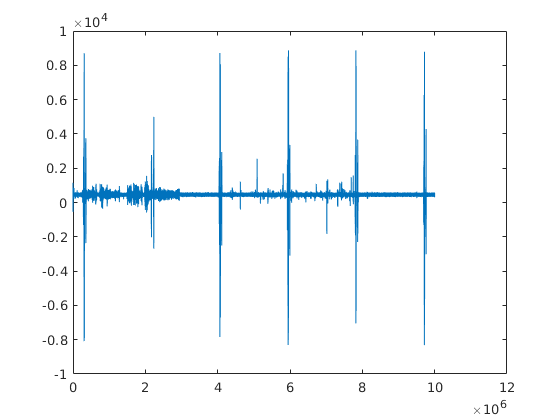

% clean artifacts clipping
figure; plot(aud_data(10000000:20000000))

for art = 1:length(all_times)
    chg_time = experiment.Conditions.all_changes(art);
    aud_data(chg_time-artifactEnd:chg_time+artifactStart) = median(aud_data);
end

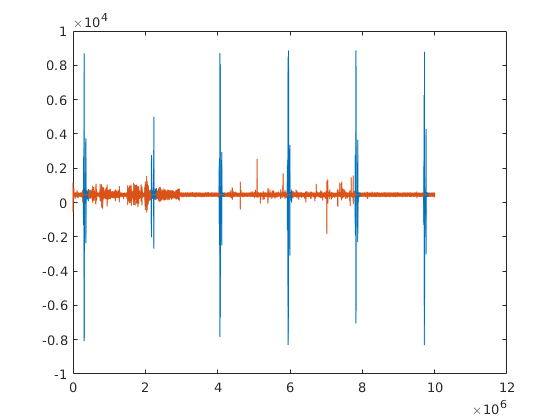

hold on; plot(aud_data(10000000:20000000))

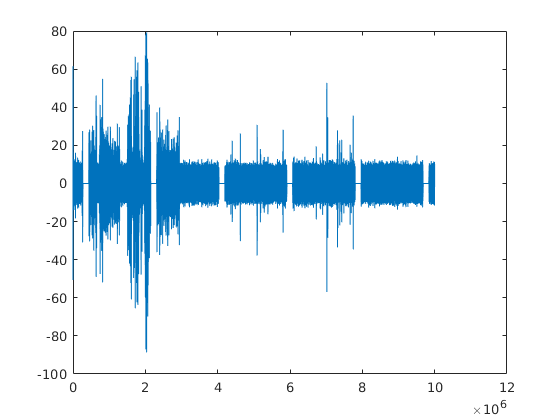

%filter data and keep just the aluminum sound componenets
[b,a] = cheby1(5,20,[10000]/15000,'high');
aud_data_filt = filtfilt(b,a,double(aud_data));
figure; plot(aud_data_filt(10000000:20000000))

% envelope aud_data
aud_data_env = envelope(aud_data_filt,300,"analytic");

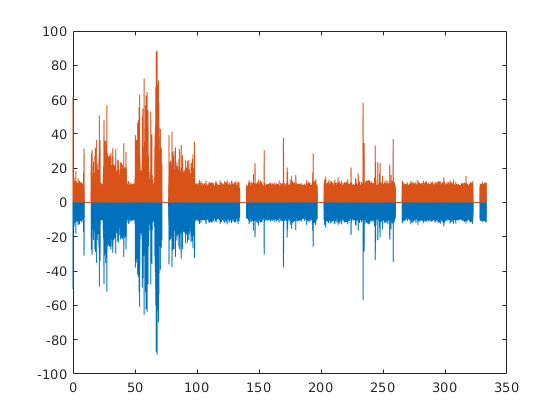

figure; plot([1:10000001]/30000,aud_data_filt(10000000:20000000))
hold on; plot([1:10000001]/30000,aud_data_env(10000000:20000000))

% filter envelope to gte only slow changes
[bn,an] = butter(3,[80]/15000,"low");
aud_data_env = filtfilt(bn,an,double(aud_data_env));

aud_data_cleaned = normalize(aud_data_env,'range',[0,1])

aud_data_cleaned =     0.0453    0.0454    0.0456    0.0457    0.0458    0.0459    0.0461    0.0462    0.0463    0.0465    0.0466    0.0467    0.0469    0.0470    0.0471    0.0473    0.0474    0.0475    0.0477    0.0478    0.0479    0.0481    0.0482    0.0483    0.0485    0.0486    0.0488    0.0489    0.0490    0.0492    0.0493    0.0494    0.0496    0.0497    0.0498    0.0500    0.0501    0.0503    0.0504    0.0505    0.0507    0.0508    0.0509    0.0511    0.0512    0.0513    0.0515    0.0516    0.0518    0.0519


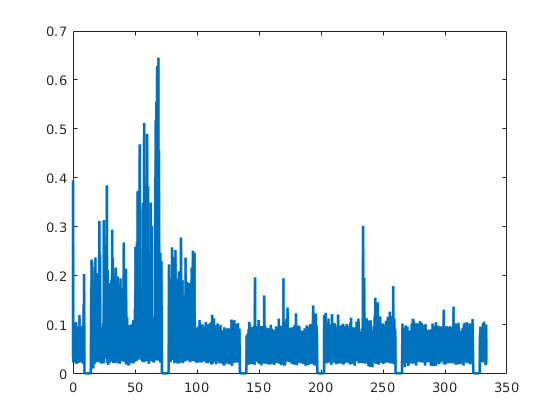

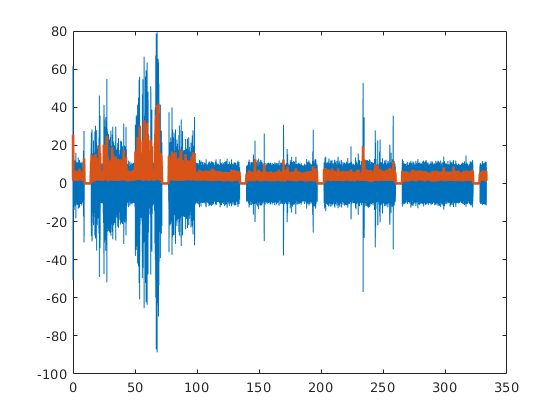

figure;plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)

% clean data below threshold
aud_data_cleaned(aud_data_cleaned<0.11) = median(aud_data_cleaned);

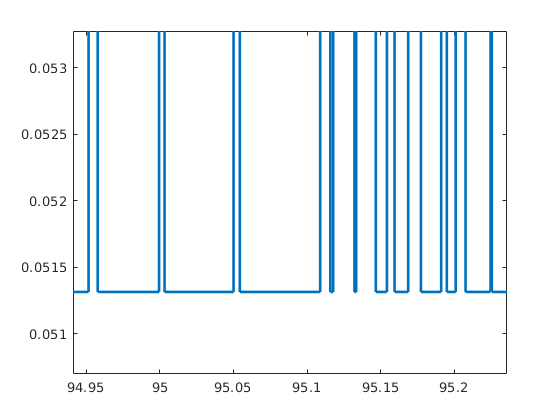

aud_data_cleaned =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


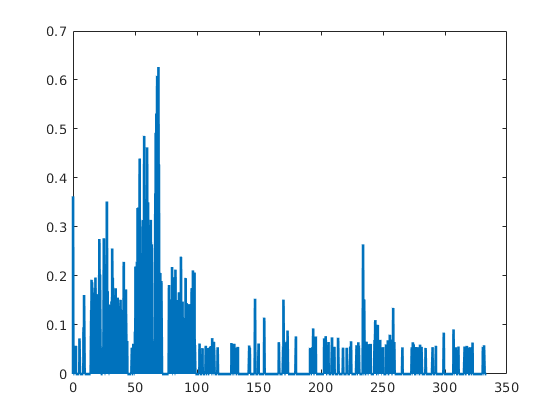


figure; plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)

experiment.sound_events.fullSound = aud_data;
experiment.sound_events.fullSoundCleaned = aud_data_cleaned;

aud_data_Alum = aud_data_cleaned(aluminumVector)

aud_data_Alum =     0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.1140    0.1130    0.1102    0.1145    0.1203    0.1150    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.1217    0.1511    0.1725    0.1696    0.1508


%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_Alum)

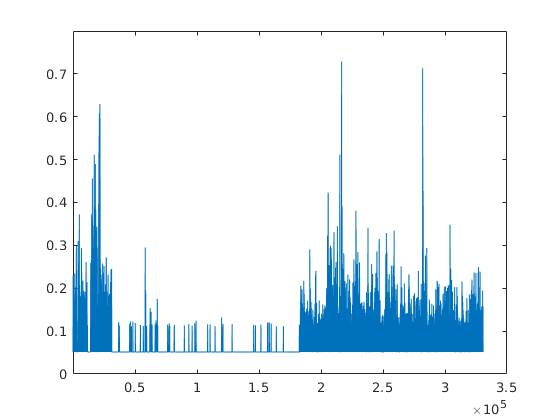

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)

[b,a] = butter(3,[2 400]/15000,'bandpass')
encoder_data = filtfilt(b,a,double(encoder_data))

figure; plot(encoder_data)

encoder_data = 1×67777280 int16 row vector
   20533   20542   20543   20547   20519   20539   20531   20537   20535   20547   20545   20547   20547   20535   20539   20534   20555   20538   20551   20527   20545   20547   20545   20542   20537   20529   20527   20537   20539   20537   20539   20539   20531   20523   20547   20536   20533   20537   20528   20546   20539   20544   20538   20544   20541   20543   20543   20546   20547   20543


% add encoder to the modal and prediction matrices

b = 	1.0e+-3 *

    0.0667         0   -0.2002         0    0.2002         0   -0.0667


a =     1.0000   -5.8332   14.1799  -18.3866   13.4130   -5.2194    0.8464


modelMatrix = encoder_data(aluminumVector)'

encoder_data = 	1.0e+04 *

    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


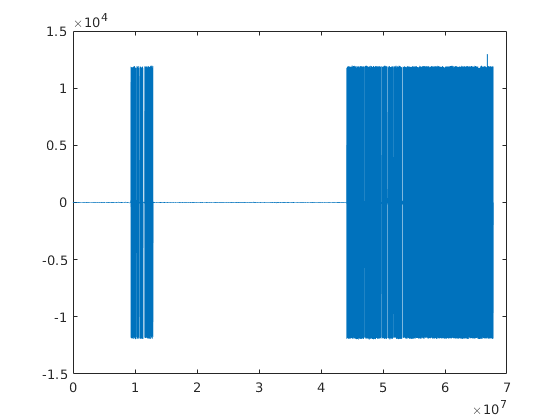

predictionMatrix = encoder_data(sampleVector)'


% import the whisking moiton vectors
[file,path] = uigetfile();

modelMatrix = 	1.0e+04 *

    0.0003
   -0.0001
   -0.0010
   -0.0014
   -0.0018
   -0.0025
   -0.0032
   -0.0039
   -0.0044
   -0.0049


cd(path)

predictionMatrix = 	1.0e+04 *

    0.0001
   -0.0001
   -0.0002
    0.0000
   -0.0002
    0.0000
   -0.0002
    0.0002
   -0.0001
   -0.0000


load(file,'motSVD_1','motion_1')

modelMatrix(:,2) = motion_1(aluminumWhiskerVector)
predictionMatrix(:,2) = motion_1(whiskingVector)
modelMatrix(:,3:22) = motSVD_1(aluminumWhiskerVector,1:20)
predictionMatrix(:,3:22) = motSVD_1(whiskingVector,1:20)


modelMatrix = 	1.0e+04 *

    0.0003    0.1787
   -0.0001    0.2401
   -0.0010    0.2169
   -0.0014    0.2424
   -0.0018    0.2054
   -0.0025    0.2120
   -0.0032    0.2499
   -0.0039    0.2590
   -0.0044    0.2459
   -0.0049    0.2320


% save the model and prediction vectors 

predictionMatrix = 	1.0e+04 *

    0.0001    0.0261
   -0.0001    0.0170
   -0.0002    0.0189
    0.0000    0.2684
   -0.0002    0.0375
    0.0000    0.0223
   -0.0002    0.0228
    0.0002    0.0129
   -0.0001    0.0056
   -0.0000    0.0074


save('model_matrices.mat','modelMatrix',"aud_data_Alum",'predictionMatrix','sampleVector','aluminumWhiskerVector')

modelMatrix = 	1.0e+04 *

    0.0003    0.1787   -0.0019   -0.0058   -0.0036    0.0030    0.0009   -0.0001   -0.0002   -0.0006    0.0026    0.0001    0.0046   -0.0012    0.0005    0.0000   -0.0014   -0.0041   -0.0015   -0.0016    0.0002    0.0011
   -0.0001    0.2401   -0.0045   -0.0059   -0.0038    0.0028    0.0026   -0.0007   -0.0007    0.0001    0.0023   -0.0008    0.0046   -0.0018    0.0003   -0.0004   -0.0018   -0.0032   -0.0007   -0.0007    0.0006    0.0004
   -0.0010    0.2169   -0.0038   -0.0057   -0.0042    0.0029    0.0015   -0.0002   -0.0002   -0.0001    0.0020   -0.0007    0.0023   -0.0011    0.0007   -0.0010   -0.0007    0.0002    0.0000    0.0004    0.0008    0.0008
   -0.0014    0.2424   -0.0053   -0.0054   -0.0040    0.0019    0.0021    0.0001   -0.0010    0.0006    0.0005   -0.0002    0.0007   -0.0005    0.0000   -0.0009   -0.0008   -0.0001    0.0020    0.0008    0.0018   -0.0003
   -0.0018    0.2054   -0.0028   -0.0056   -0.0031    0.0028    0.0017    0.0002   -0.0001

save('FVB109_904.mat',"experiment")

predictionMatrix = 	1.0e+04 *

    0.0001    0.0261    0.0029   -0.0003   -0.0002    0.0000    0.0000   -0.0001    0.0001    0.0000    0.0002   -0.0001    0.0002   -0.0002   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0001   -0.0001    0.0001
   -0.0001    0.0170    0.0026   -0.0002   -0.0001   -0.0000   -0.0000    0.0001    0.0002   -0.0002    0.0003    0.0002    0.0001   -0.0003   -0.0002    0.0001   -0.0001    0.0000   -0.0001   -0.0002   -0.0001    0.0002
   -0.0002    0.0189    0.0028   -0.0001   -0.0001    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0002    0.0001   -0.0001    0.0000   -0.0000    0.0001   -0.0001    0.0002   -0.0001   -0.0000   -0.0001    0.0000
    0.0000    0.2684    0.0027   -0.0003   -0.0001   -0.0002   -0.0001   -0.0001    0.0000   -0.0000   -0.0002    0.0002    0.0000    0.0000    0.0003   -0.0003   -0.0001   -0.0000   -0.0001    0.0000   -0.0001    0.0000
   -0.0002    0.0375   -0.0041   -0.0071    0.0018   -0.0031    0.0001    0.0004    0

clearvars -except modelMatrix aud_data_Alum predictionMatrix sampleVector aluminumWhiskerVector

% load model and prediction if needed
%cd('/home/ben/Z/FVB/270721/849')                   
load('model_matrices.mat')

% create traintest spli idx for testing model
modelPart = cvpartition(length(modelMatrix),"HoldOut",0.1)
idxTrain = training(modelPart)
idxTest = test(modelPart)

% split data to train test
modelTrain = modelMatrix(idxTrain,:)
modelTest = modelMatrix(idxTest,:)

aud_data_Train = aud_data_Alum(idxTrain)

modelPart = Hold-out cross validation partition
   NumObservations: 330703
       NumTestSets: 1
         TrainSize: 297633
          TestSize: 33070

aud_data_test = aud_data_Alum(idxTest)

idxTrain = 330703×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1


%aud_data_cleaned = normalize(aud_data_cleaned,'range')

idxTest = 330703×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0


% savr model to the experiment object
experiment.predictionModel = trainedModel;

modelTrain = 	1.0e+04 *

    0.0003    0.1787   -0.0019   -0.0058   -0.0036    0.0030    0.0009   -0.0001   -0.0002   -0.0006    0.0026    0.0001    0.0046   -0.0012    0.0005    0.0000   -0.0014   -0.0041   -0.0015   -0.0016    0.0002    0.0011
   -0.0001    0.2401   -0.0045   -0.0059   -0.0038    0.0028    0.0026   -0.0007   -0.0007    0.0001    0.0023   -0.0008    0.0046   -0.0018    0.0003   -0.0004   -0.0018   -0.0032   -0.0007   -0.0007    0.0006    0.0004
   -0.0010    0.2169   -0.0038   -0.0057   -0.0042    0.0029    0.0015   -0.0002   -0.0002   -0.0001    0.0020   -0.0007    0.0023   -0.0011    0.0007   -0.0010   -0.0007    0.0002    0.0000    0.0004    0.0008    0.0008
   -0.0014    0.2424   -0.0053   -0.0054   -0.0040    0.0019    0.0021    0.0001   -0.0010    0.0006    0.0005   -0.0002    0.0007   -0.0005    0.0000   -0.0009   -0.0008   -0.0001    0.0020    0.0008    0.0018   -0.0003
   -0.0018    0.2054   -0.0028   -0.0056   -0.0031    0.0028    0.0017    0.0002   -0.0001 

% Get predictions from regression learner (bagged tree ensamble)

modelTest = 	1.0e+04 *

   -0.0039    0.2590   -0.0057   -0.0048   -0.0018   -0.0007    0.0011   -0.0018    0.0005    0.0034   -0.0007   -0.0002   -0.0017   -0.0021   -0.0015    0.0024    0.0002   -0.0025    0.0032    0.0016   -0.0003    0.0011
   -0.0119    0.2525   -0.0061   -0.0037   -0.0011   -0.0020    0.0007   -0.0031    0.0007    0.0025    0.0001   -0.0012   -0.0008   -0.0011   -0.0020    0.0022    0.0009   -0.0017    0.0005    0.0019   -0.0008    0.0021
   -0.0128    0.1770   -0.0037   -0.0024   -0.0009   -0.0001    0.0000   -0.0004    0.0001    0.0013   -0.0001    0.0000   -0.0010   -0.0001   -0.0004    0.0002    0.0009   -0.0006    0.0006    0.0000   -0.0002    0.0008
   -0.0159    0.1978   -0.0030   -0.0036   -0.0012    0.0008    0.0009   -0.0015    0.0002    0.0010    0.0001    0.0004    0.0000   -0.0011   -0.0009    0.0003    0.0003   -0.0019    0.0008   -0.0003    0.0001    0.0014
   -0.0161    0.2251   -0.0059   -0.0024   -0.0001   -0.0029   -0.0002   -0.0024   -0.0012  

y = trainedModel.predictFcn(predictionMatrix)

% find all y values aboe threshold and find the start of each event 

aud_data_Train =     0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.1140    0.1130    0.1102    0.1203    0.1150    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.1725    0.1696    0.1508    0.1342    0.1218    0.1117    0.0513    0.1110    0.0513    0.0513


aud_data_test =     0.0513    0.0513    0.0513    0.1145    0.0513    0.1217    0.1511    0.1113    0.0513    0.0513    0.0513    0.1140    0.0513    0.0513    0.0513    0.2142    0.1883    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.1132    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.2087    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513    0.0513


[times] = event_detection(y,500*0.4)



% find events sample time
times_prediction = times
times = sampleVector(times);

experiment.predictedSound.y = y
experiment.predictedSound.sampleVector = sampleVector
experiment.predictedSound.events.all = times_prediction

% Add the events top the experiment object
experiment.sound_events.all = times

artifactStart = experiment.Conditions.artifact_times(2) * 30
artifactEnd = experiment.Conditions.artifact_times(1) * 30
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = all_times(1:22,:)

times = experiment.sound_events.all;
times_prediction = experiment.predictedSound.events.all

`Divide the events to the experiment condition`

% Aluminum times
aluminumTimes = all_times(experiment.Conditions.condition_classification(1:18) == 1,:)
aluminumEvents = []
experiment.predictedSound.events.aluminum = [];
for al = 1:length(aluminumTimes)
    tempEvents = times(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))
    tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    experiment.predictedSound.events.aluminum = [experiment.predictedSound.events.aluminum;tempPredict]
end

% non times
nonTimes = all_times(experiment.Conditions.condition_classification(1:18) == 3,:)
experiment.predictedSound.events.non = [];
nonEvents = []
for non = 1:length(nonTimes)
    tempInd = times(find(times > nonTimes(non,1) & times < nonTimes(non,2)))
    tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]
    experiment.predictedSound.events.non = [experiment.predictedSound.events.non;tempPredict];
end

% muted times
mutedTimes = all_times(experiment.Conditions.condition_classification(1:18) == 2,:)
experiment.predictedSound.events.muted = [];
mutedEvents = []
for mut = 1:length(mutedTimes)
    tempInd = times(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))
    tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    experiment.predictedSound.events.muted = [experiment.predictedSound.events.muted;tempPredict];
end

timeWind = 1;
numBins = 20;

rasters_aluminum = {}
psth_aluminum = []
for un = 1:length(experiment.Units.good.id)
    rasters_aluminum{un} = createRaster(aluminumEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminum(un,:) = psth(rasters_aluminum{un},numBins);
end

rasters_muted = {}
psth_muted = []
for un = 1:length(experiment.Units.good.id)
    rasters_muted{un} = createRaster(mutedEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_muted(un,:) = psth(rasters_muted{un},numBins);
end

rasters_non = {}
psth_non = []
for un = 1:length(experiment.Units.good.id)
    rasters_non{un} = createRaster(nonEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_non(un,:) = psth(rasters_non{un},numBins);
end

rasters_aluminumMua = {}
psth_aluminumMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_aluminumMua{un} = createRaster(aluminumEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminumMua(un,:) = psth(rasters_aluminumMua{un},numBins);
end

rasters_mutedMua = {}
psth_mutedMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_mutedMua{un} = createRaster(mutedEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_mutedMua(un,:) = psth(rasters_mutedMua{un},numBins);
end

rasters_nonMua = {}
psth_nonMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_nonMua{un} = createRaster(nonEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_nonMua(un,:) = psth(rasters_nonMua{un},numBins);
end

psth_aluminumAll = [psth_aluminum;psth_aluminumMua]

psth_mutedAll = [psth_muted;psth_mutedMua]
psth_nonAll = [psth_non;psth_nonMua]

aud_units = find(experiment.evokedEvents.pVal(:,2) == 1);
[~,time_vector] = psth(rasters_non{1},numBins);

mutSTD = std(psth_mutedAll(aud_units,:))/sqrt(length(aud_units))
alumSTD = std(psth_aluminumAll(aud_units,:))/sqrt(length(aud_units))
nonSTD = std(psth_nonAll(aud_units,:))/sqrt(length(aud_units))

figure; 
hold on

plot(time_vector,mean(psth_aluminumAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Aluminum)
errorbar(time_vector,mean(psth_aluminumAll(aud_units,:)),alumSTD,'LineWidth',0.1,'Color',experiment.color.Aluminum)
hold on
plot(time_vector,mean(psth_mutedAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Muted)
errorbar(time_vector,mean(psth_mutedAll(aud_units,:)),mutSTD,'LineWidth',0.1,'Color',experiment.color.Muted)
plot(time_vector,mean(psth_nonAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.noObject)
errorbar(time_vector,mean(psth_nonAll(aud_units,:)),nonSTD,'LineWidth',0.1,'Color',experiment.color.noObject)

meanSound.aluminumMean = meanMatrix(experiment.predictedSound.events.aluminum,1,400)
figure; plot(mean(y(meanSound.aluminumMean)))
hold on
meanSound.mutedMean = meanMatrix(experiment.predictedSound.events.muted,1,400)
plot(mean(y(meanSound.mutedMean)))
meanSound.nonMean = meanMatrix(experiment.predictedSound.events.non,1,400)
plot(mean(y(meanSound.nonMean)))

meanSound.aluminumMean = meanMatrix(aluminumEvents,1,30000);
figure; plot(mean(experiment.sound_events.fullSound(meanSound.aluminumMean)));
hold on;
meanSound.mutedMean = meanMatrix(mutedEvents,1,30000);
plot(mean(experiment.sound_events.fullSound(meanSound.mutedMean)));
meanSound.nonMean = meanMatrix(nonEvents,1,30000)
plot(mean(experiment.sound_events.fullSound(meanSound.nonMean)));

experiment.sound_events.aluminum = aluminumTimes;
experiment.sound_events.muted = mutedTimes;
experiment.sound_events.non = nonTimes;
experiment.PSTHs.alum = psth_aluminumAll;
experiment.PSTHs.muted = psth_mutedAll;
experiment.PSTHs.non = psth_nonAll;
%experiment.PSTHs.audUnits = aud_units;
experiment.PSTHs.time_vector = time_vector;

experiment.sound_events.aluminumEvents = aluminumEvents;
experiment.sound_events.mutedEvents = mutedEvents;
experiment.sound_events.nonEvents = nonEvents;

%params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_849.m';
run(params)

save([expName,'.mat'],'experiment')